# df

load("final_sel_feat_cnv.mat");
load("final_sel_feat_mrna.mat")
load("final_sel_feat_mut.mat");
load("final_sel_feat_meth.mat");
%writetable( final_sel_feat_cnv,'./NCA_outputs/cnv_sel_features_39genes.xlsx', 'WriteRowNames',true);
% writetable( final_sel_feat_meth,'./NCA_outputs/meth_sel_features_18genes.xlsx', 'WriteRowNames',true);
% writetable( final_sel_feat_mrna,'./NCA_outputs/mrna_sel_features_20genes.xlsx', 'WriteRowNames',true);
% writetable( final_sel_feat_mut,'./NCA_outputs/mut_sel_features_28genes.xlsx', 'WriteRowNames',true);

load("drug_resp.mat");
cnv = (table2array(final_sel_feat_cnv))';
rna = final_sel_feat_mrna';
mutation = (table2array(final_sel_feat_mut))';
methylation = (table2array(final_sel_feat_meth))';
% clinical = (table2array(clinical))';
t = drug_resp';
x= {cnv; rna; mutation; methylation};

%rng(0,'twister'); % For reproducibility
% N = 100;
% targets = rand(30,10)';
% input1 = rand(N,30);
% input2 = rand(N,30);

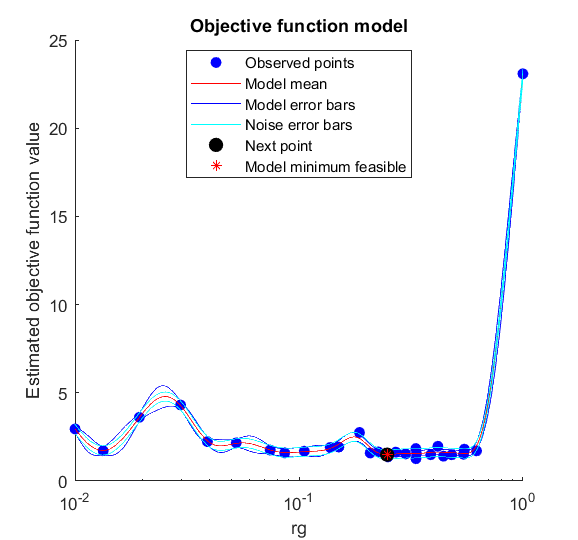

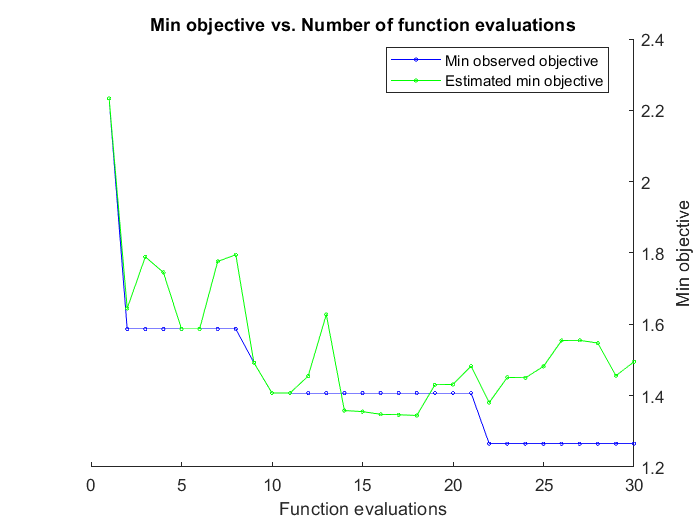

    2.2335

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |           rg |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      2.2335 |      109.86 |      2.2335 |      2.2335 |     0.038987 |
    1.5869

|    2 | Best   |      1.5869 |      119.67 |      1.5869 |      1.6447 |      0.20787 |
    1.5950

|    3 | Accept |       1.595 |      123.44 |      1.5869 |      1.7892 |     0.086324 |
    1.7119

|    4 | Accept |      1.7119 |      64.555 |      1.5869 |      1.7456 |      0.62032 |
    1.6516

|    5 | Accept |      1.6516 |      114.82 |      1.5869 |       1.587 |      0.22599 |
    1.9018

|    6 | Accept |      1.9018 |      121.62 |      1.5869 |       1.587 |      0.13791 |
    1.7540

|    7 | Accept |       1.

rng(1);
cv = cvpartition(numel(t), 'Holdout', 0.10);
% Define hyperparameters to optimize     
vars = [%optimizableVariable('hiddenLayerSize', [5 10], 'Type', 'integer');
        optimizableVariable('rg', [1e-2 1], 'Transform', 'log');];
% Optimize
%minfn = @(T)kfoldLoss(x,t , T.hiddenLayerSize,cv,T.rg);
minfn = @(T)kfoldLoss(x, t,[10,9], cv, T.rg);

results = bayesopt(minfn, vars,'IsObjectiveDeterministic', false,...
    'AcquisitionFunctionName', 'expected-improvement-plus');

T = bestPoint(results);

rng(1);
k=10;
cvnn = cvpartition(t(1,:),'KFold',k)

cvnn = K-fold cross validation partition
   NumObservations: 43
       NumTestSets: 10
         TrainSize: 39  38  38  38  39  39  39  39  39  39
          TestSize: 4  5  5  5  4  4  4  4  4  4


hiddenLayerSize = [10, 10];
trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation.
net = fitnet(hiddenLayerSize, trainFcn);
net.performFcn = 'mse'; 

net.performParam.normalization = 'none';
net.performParam.regularization =0.4833;
net.performParam.regularization;

ans = 0.4833

ans =      9     4     1    38    19    33    27    40    11    30    32    31     5    39    35    29    17    20    14     3    34    18    28    37     6    24    21    23     2    41    15    22    26


ans =     42    43     8    12    36    10


ans =      7    13    16    25


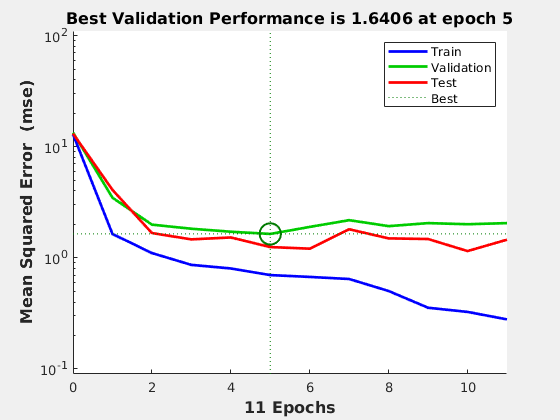

performance = 0.9080

mseError = 1.7040

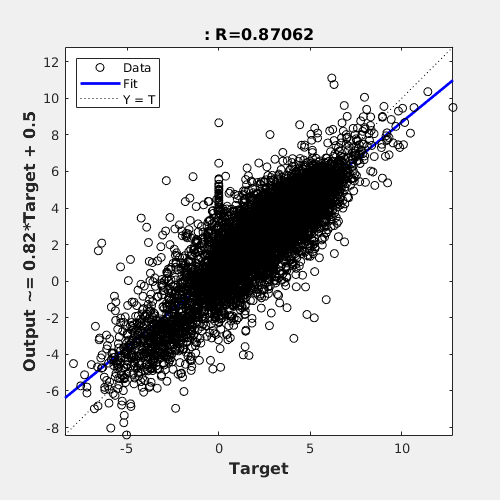

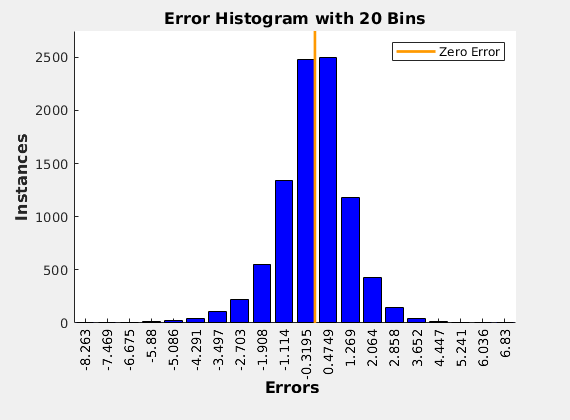

ans =     26    34     2    10    32    11    37    12     6    38    30    42    17     7     4    25     3    31    28    27    29    24     5    33    13    21    22    14     1    16    23    41    18


ans =     35    40    39    43     9


ans =      8    15    19    20    36


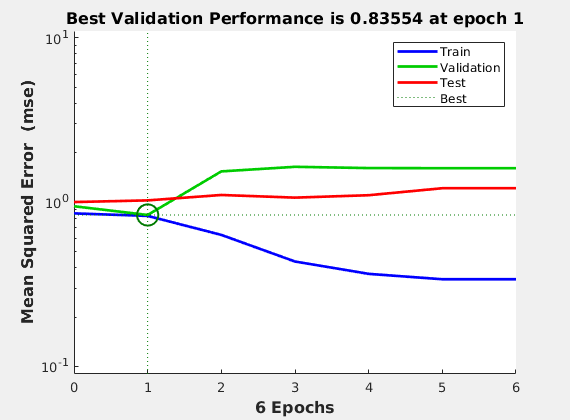

performance = 0.8710

mseError = 1.6372

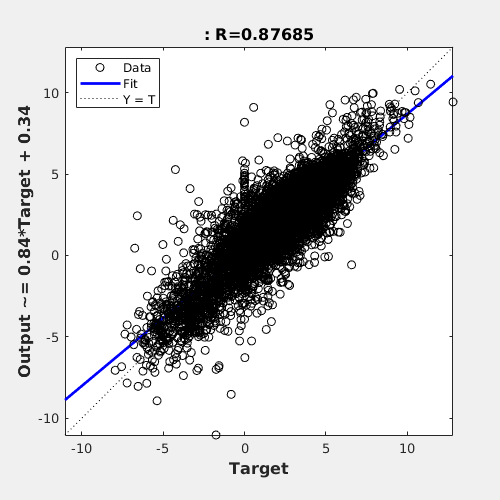

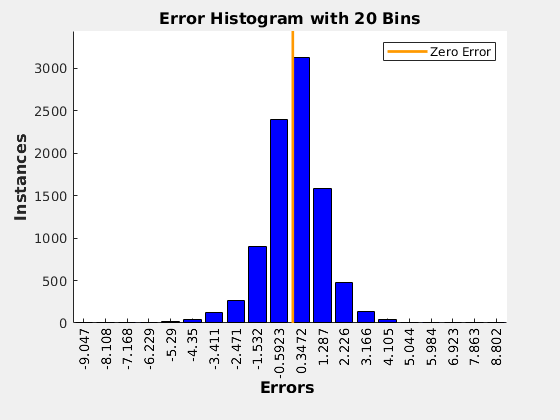

ans =      8    24    23    21    19    34     6    15    10    29     9    43     7    35     5    27    26    17     2    16    39    25    36    22    41     1    28     4    30    11    20    42    12


ans =     38     3    31    13    33


ans =     14    18    32    37    40


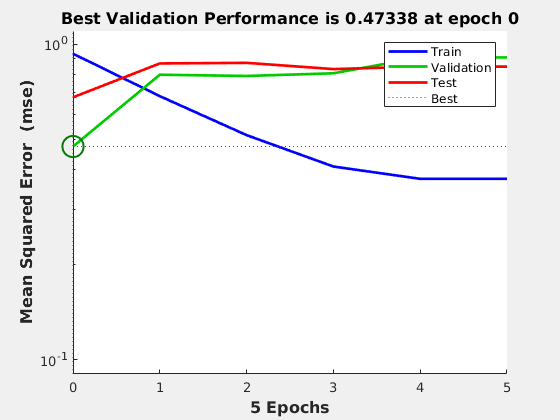

performance = 0.8710

mseError = 1.6372

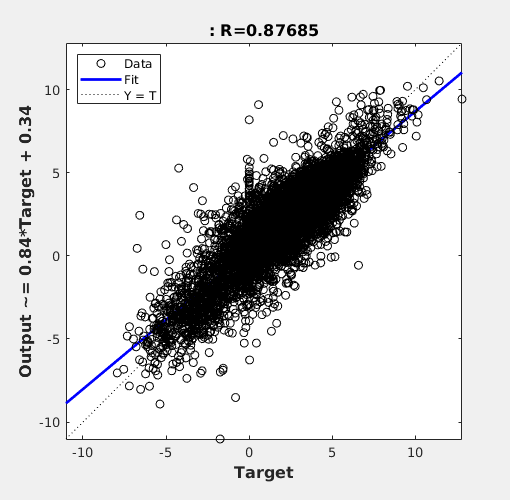

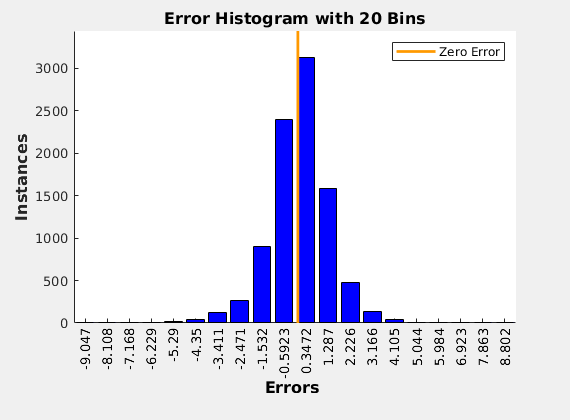

ans =     37    29    27    19    31    23    17    40    39    28    16    22    18    10    34    36     2     1    11     7    38    13    25     4    15    14    21     9    30    20    24    32    42


ans =      6    41    12     8    26


ans =      3     5    33    35    43


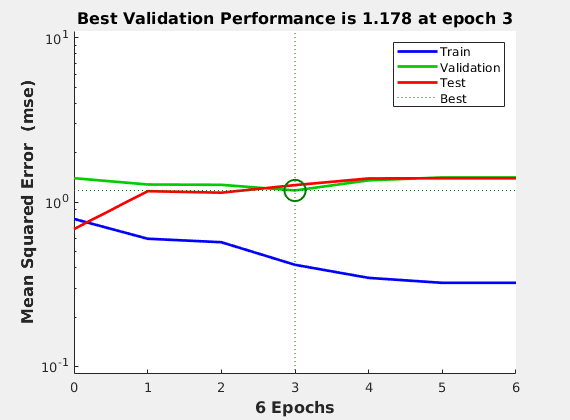

performance = 0.6250

mseError = 1.1685

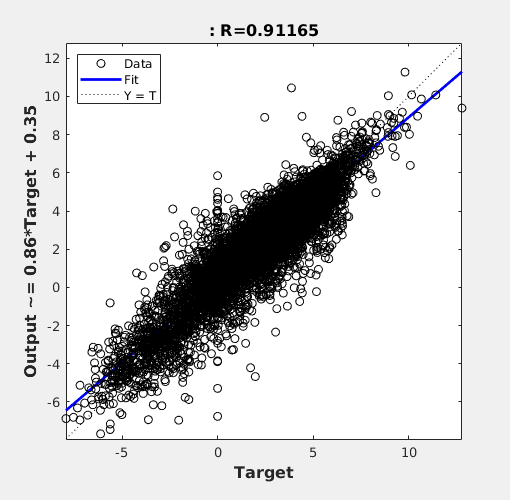

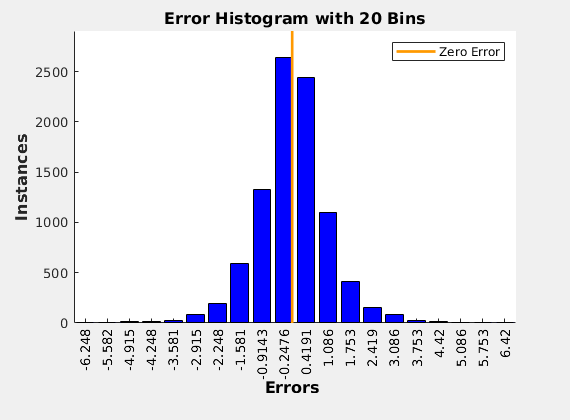

ans =      3    40    43    31    29    14    42    20    39    35    10    27    38     6    37    26    11    12    32    33    21     7     9    22    15    30     8    23    17    18    16    19     4


ans =     28    13    36     5    24    25


ans =      1     2    34    41


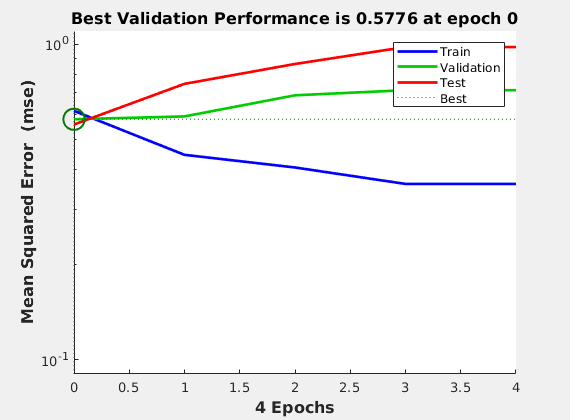

performance = 0.6250

mseError = 1.1685

ans =      9    31    34    40    25     8    21    30     5    42    19    17    10    41    27    43    24     7    33     1    36    37    18     4     2    13    32     6    20    22    16     3    38


ans =     29    23    39    14    15    35


ans =     11    12    26    28


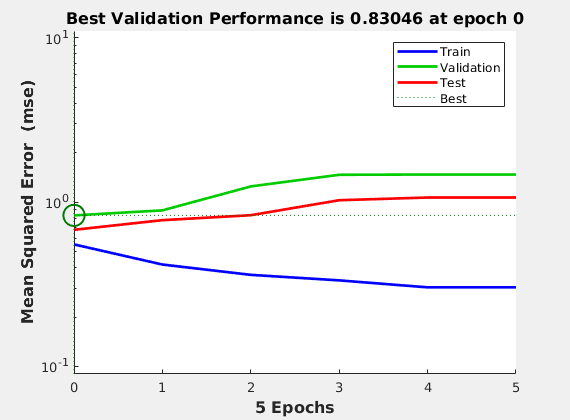

performance = 0.6250

mseError = 1.1685

ans =      8    13    11    41     2    21     1    33    39    20    14    12    36    34    25     3    27    17    23    24    32    38    31    37    42    15    16    18     9    26     7    28    19


ans =     35    40     4    29    43     5


ans =      6    10    22    30


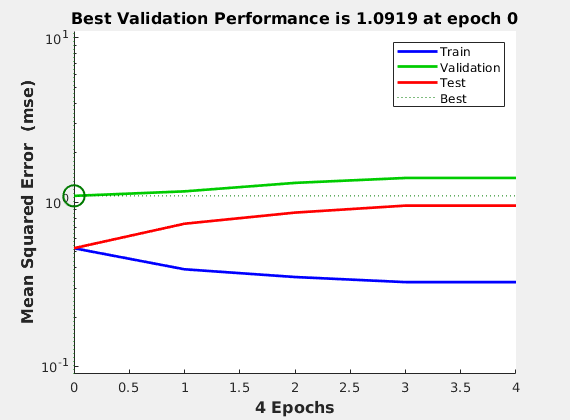

performance = 0.6250

mseError = 1.1685

ans =     10    41    31     3    34    29    35    18    32    30    38     2     6    13    12    37    16    15    19    22     8     4    25    17    39     7    43    20    42    23     1    33     5


ans =     36    26    14    28    40    11


ans =      9    21    24    27


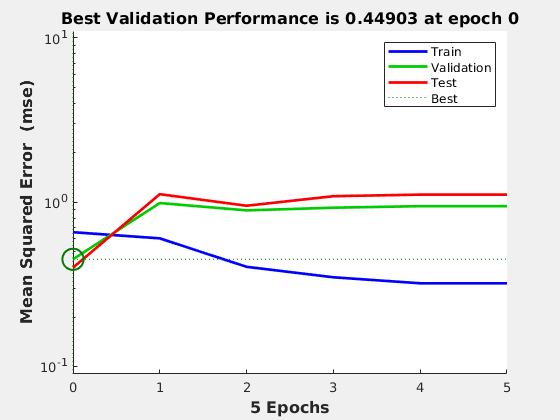

performance = 0.6250

mseError = 1.1685

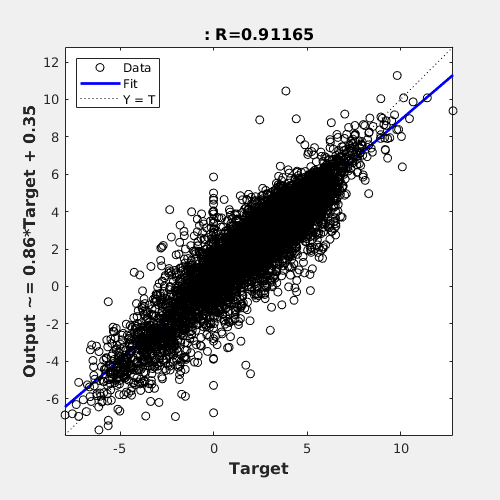

ans =     26     8    10     9     6    25     5    20    40     2    14    28    32    34    19    27    42    24    31    11    29    43    22    41    37     7     3    39    12    15    16    21    33


ans =     36     1    18    35    30    13


ans =      4    17    23    38


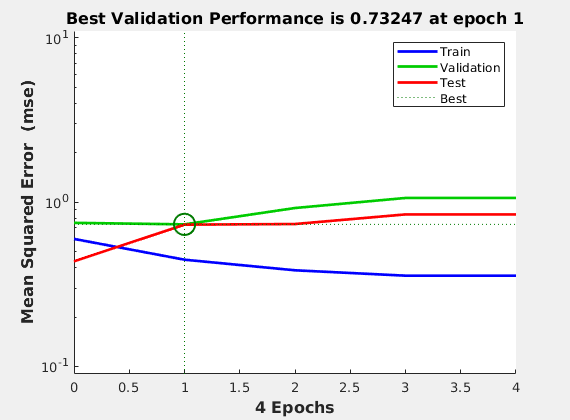

performance = 0.5339

mseError = 0.9928

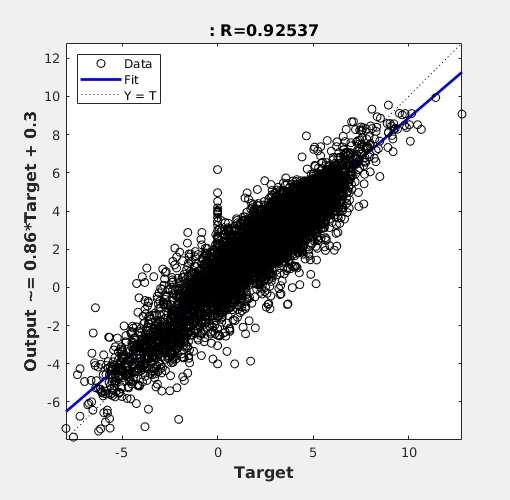

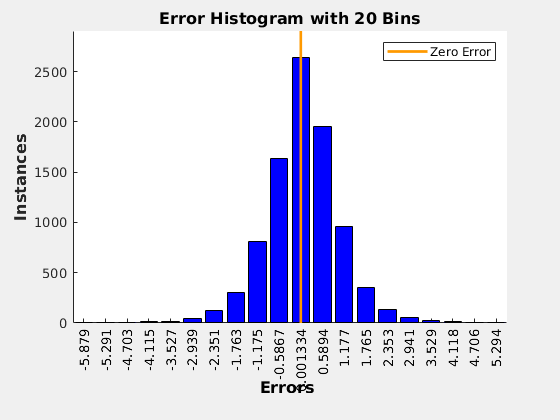

ans =     37    30    32    21     6    33    35     1    28    15    41    10    16    18     3    26    19     4     7    34    17    43     9    23    11     5    14    38    25    20     8    36    24


ans =     13     2    12    27    40    22


ans =     29    31    39    42


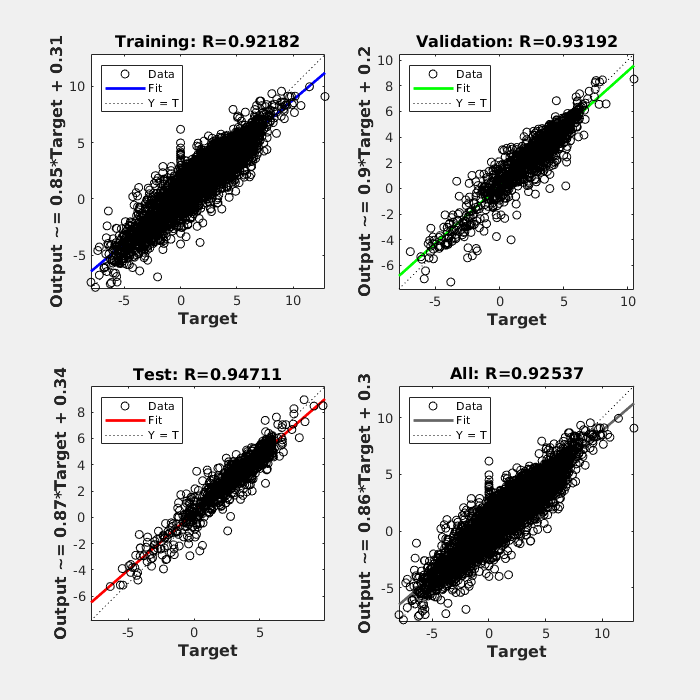

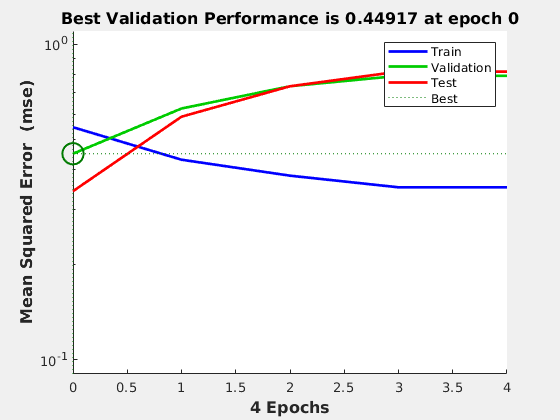

performance = 0.5339

mseError = 0.9928

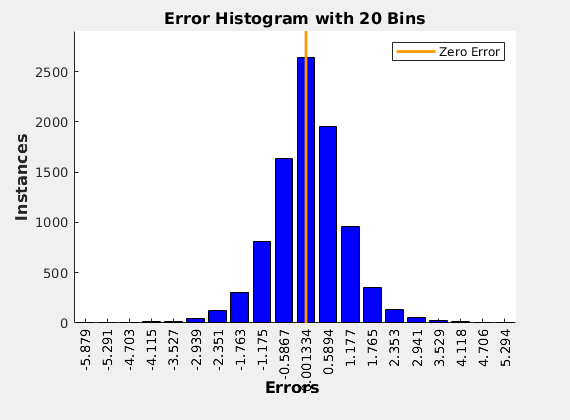

for i=1:k
      testIdx = cvnn.test(i);               %# get indices of test instances
      trainIdx = cvnn.training(i) ;                  %# get indices training instances
      trInd = find(trainIdx);
      tstInd = find(testIdx);
      trInd_r = trInd(randperm(length(trInd)));
      ind1=(vertcat(trInd_r,tstInd))'; 
      Q1=length(trInd_r);
      Q2=length(tstInd);
     
      net.divideFcn = 'divideind'; 
      [net.divideParam.trainInd, net.divideParam.valInd, net.divideParam.testInd] = divideind(ind1,1:33,33:Q1,Q1+(1:Q2));
      net.divideParam.trainInd
      net.divideParam.valInd
      net.divideParam.testInd
      net.numinputs = 4;
      %net.inputConnect = [1 1 1 1 1 1 1;0 0 0 0 0 0 0];
      net.inputConnect = [1 1 1 1; 0 0 0 0;0 0 0 0];
      %net.inputConnect = [1 1 1 1; 0 0 0 0]
      %train the network
      [net,tr] = train(net,x,t);
      
      figure, plotperform(tr);
   
      y = net(x);
      y=cell2mat(y);
      e = gsubtract(t,y);
      performance = perform(net,t,y)
      %ypred=cell2mat(y);
      mseError = mse(t-y)
      figure, plotregression(t,y);
      figure, ploterrhist(e);
      %disp(mseError)      
end